clear;
clc;

# **Kinematic model for nonholonomic mobile robot**

**This document derives the canonical simplified model**

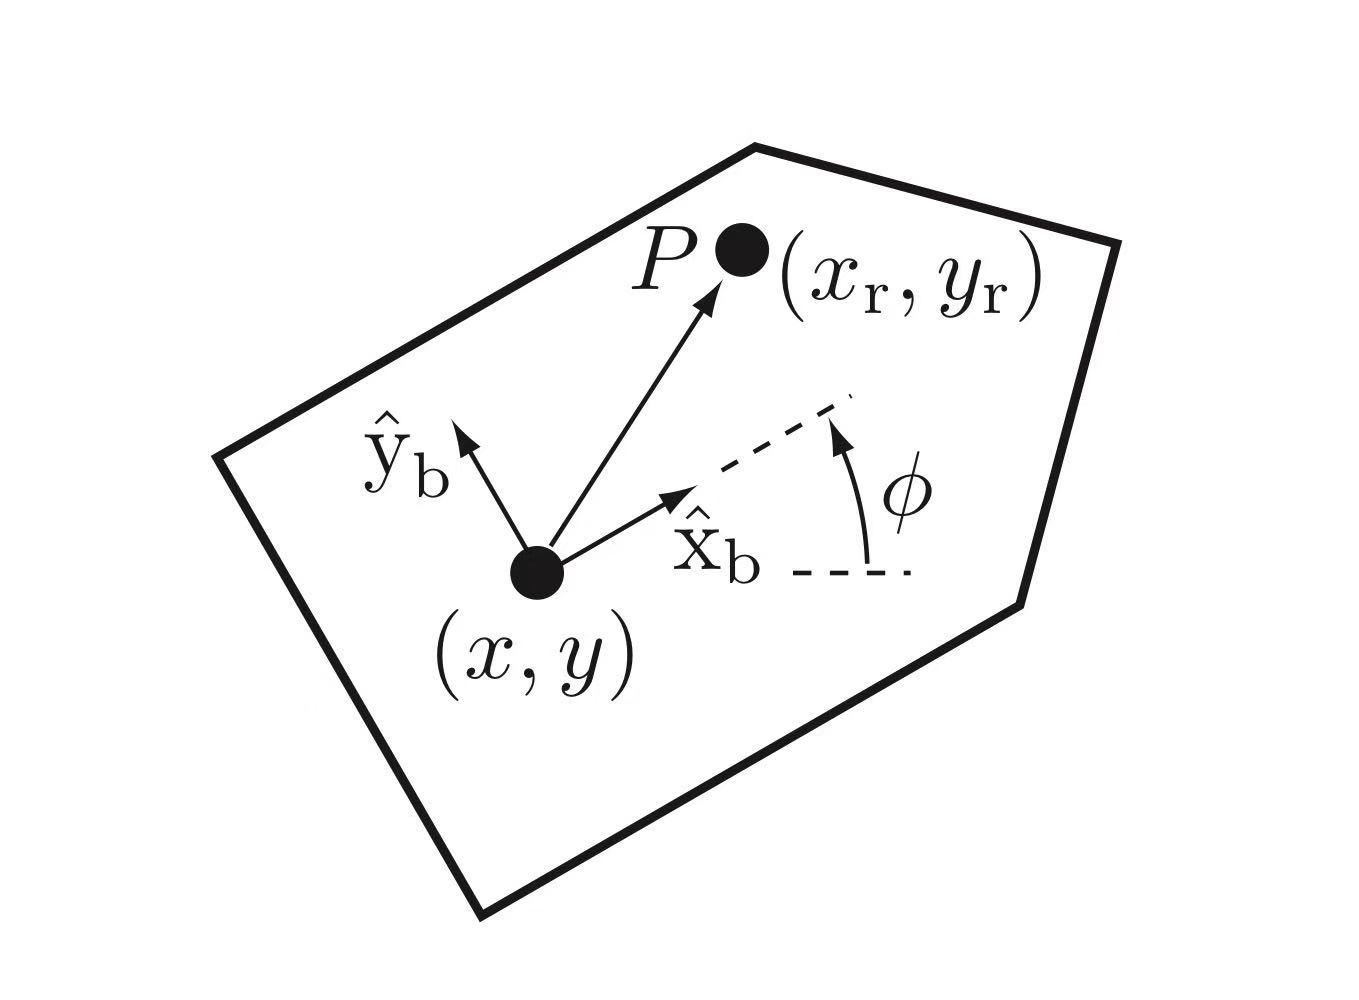

Figure of the nonholonomic mobile robot

#### Define the varibles

syms phi x y   % state varibles
syms v omega    % control varibles
syms Ts         % Sampling time

**Define the state and input vectors**

state = [phi; x; y];    % state vector
input = [v; omega];     % input vector

#### Define the nonlinear transition function

syms f [3 1]    % transition function
f(1) = omega;
f(2) = cos(phi)*v;
f(3) = sin(phi)*v;
disp(f);

$$\left(\begin{array}{c} \omega \\ v\,\cos\left(\varphi \right)\\ v\,\sin\left(\varphi \right) \end{array}\right)$$

**Calculate the Jacobian**

A = jacobian(f, state);
B = jacobian(f, input);
A = simplify(A);
B = simplify(B);

$$R = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \cos\left(\varphi \right) & 0 & 0 & -v\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right) & 0 & 0 & v\,\cos\left(\varphi \right) \end{array}\right)$$

ans = 3

disp(A);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ -v\,\sin\left(\varphi \right) & 0 & 0\\ v\,\cos\left(\varphi \right) & 0 & 0 \end{array}\right)$$

disp(B);

$$\left(\begin{array}{cc} 0 & 1\\ \cos\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & 0 \end{array}\right)$$

**Generate the MATLAB Function**

% Create StateFcn.m
matlabFunction(f,'File','stateFcnBase', ...
    'Vars',{state, input});

% Create StateJacobianFcn.m 
matlabFunction(A, B,'File','stateJacobianFcnBase',...
    'Vars',{state,input});